# Intro to Computational Imaging (ci) Classes

ciCamera is one of a set of classes that allow experimentation with computational imaging more directly than the structures they encapsulate (scene, oi, sensor, and ip). Along with ciScene, ciCModule, and ciIP, it provides a programmable wrapper that allows users to create "cameras" that have a variety of algorithms for deciding how to capture a scene, and then how to process one or more captures, potentially even from more than one camera module (ciCModule). 

History: Initial Version: D. Cardinal 12/2020, iset scene support added 1/2021

## Initialize our Computational Camera

ieInit();
% some timing code, just to see how fast we run...
setpref('ISET', 'benchmarkstart', cputime); 
setpref('ISET', 'tStart', tic);

% ciBurstCamera is a sub-class of ciCamera that implements simple HDR and Burst
% capture and processing
ourCamera = ciBurstCamera(); 

% We'll use a pre-defined sensor for our Camera Module, and let it use
% default optics for now. We can then assign the module to our camera:
sensor = sensorFromFile('ar0132atSensorRGB'); 
% Cameras can eventually have more than one module (lens + sensor)
% but for now, we just create one using our sensor
ourCamera.cmodules(1) = ciCModule('sensor', sensor); % default

## Create our Scene

The Cornell Box + Stanford Bunny is part of iset3d, and is set up to help us by labeling the assets in such a way that we can add motion to them as they are rendered by pbrt. You can use the sliders below to control the lighting level (mean luminance) of the rendered scene, as well as the number of rays per pixel pbrt uses and its "film" resolution. We've kept the defaults low to speed up rendering, but for real experiments you may want to increase them:


sceneLuminance = 200

sceneLuminance = 200

numRays = 64

numRays = 64

filmResolution = 256

filmResolution = 256

pbrtLensFile = false

pbrtLensFile = logical
   0


sceneChoice = "Cornell Box with Bunny"

sceneChoice = "Cornell Box with Bunny"

apertureDiameter = 6% in mm

apertureDiameter = 6

if strcmp(sceneChoice, "Cornell Box with Bunny")
    scenePath = 'Cornell_BoxBunnyChart';        
    sceneName = 'cornell box bunny chart';
else
    scenePath = 'ChessSet';
    sceneName = 'chessSet';
end

if pbrtLensFile
    pbrtCIScene = ciScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance, ...
    'lensFile','dgauss.22deg.3.0mm.json',...
    'apertureDiameter', apertureDiameter);
else
    pbrtCIScene = ciScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance);
end

Read 11 materials
Read 3 textures
Reading C4D geometry information.


ourCamera.cmodules(1).sensor = ...
    sensorSet(ourCamera.cmodules(1).sensor, ...
    'size', [filmResolution, filmResolution]);


## Let's Look at the Camera we've Created

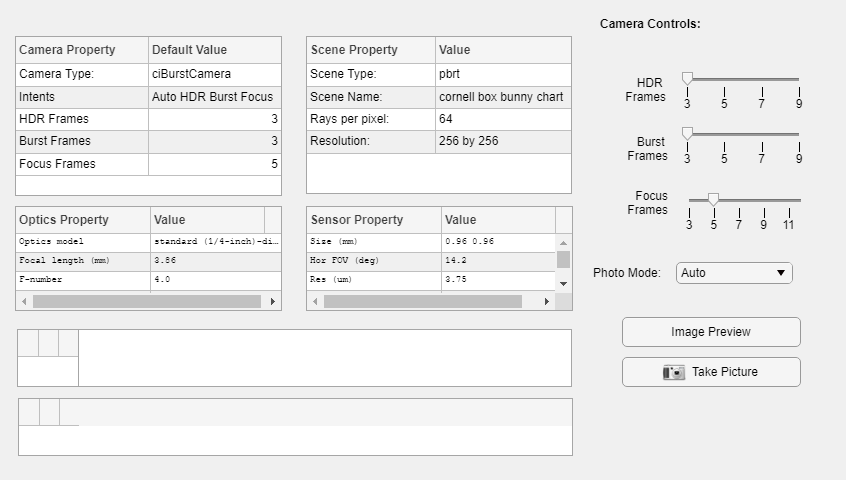

ciCameraWindow(ourCamera, pbrtCIScene);

## Set an Object in Motion in our PBRT Scene

We can set any named object in the asset tree of a pbrt scene in motion using by adding values to the .objectMotion array. Here we'll set the Stanford bunny (labeled as "Default_B" in the asset tree) into motion with a vertical movement (middle term of the first triplet) and a tiny rotation (the second triplet). Later we'll show how the camera can also be set in motion:

% Move the bunny up, with slow rotation
if strcmp(sceneName, 'cornell box bunny chart')
    pbrtCIScene.objectMotion = {{'Default_B', [0, 15, 0], [1, 1, 1]}};
end

## Take Pictures using Auto, HDR, and Burst Intents

For the simplest case we ask our camera to take some pictures using pre-defined intents. By deault our camera assumes the 'Auto' intent. We also demonstrate 'Burst', which will capture more frames if the camera type we are using supports it. 'HDR' also fires a burst, but bracketed. Our default camera sums the frames in Burst mode, and chooses the highest non-saturated value at each pixel for HDR mode.

New light added.
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_depth.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cam

ans = "Scene luminance is: 200.000000"

New light added.
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_depth.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cam

ans = "Scene luminance is: 200.000000"

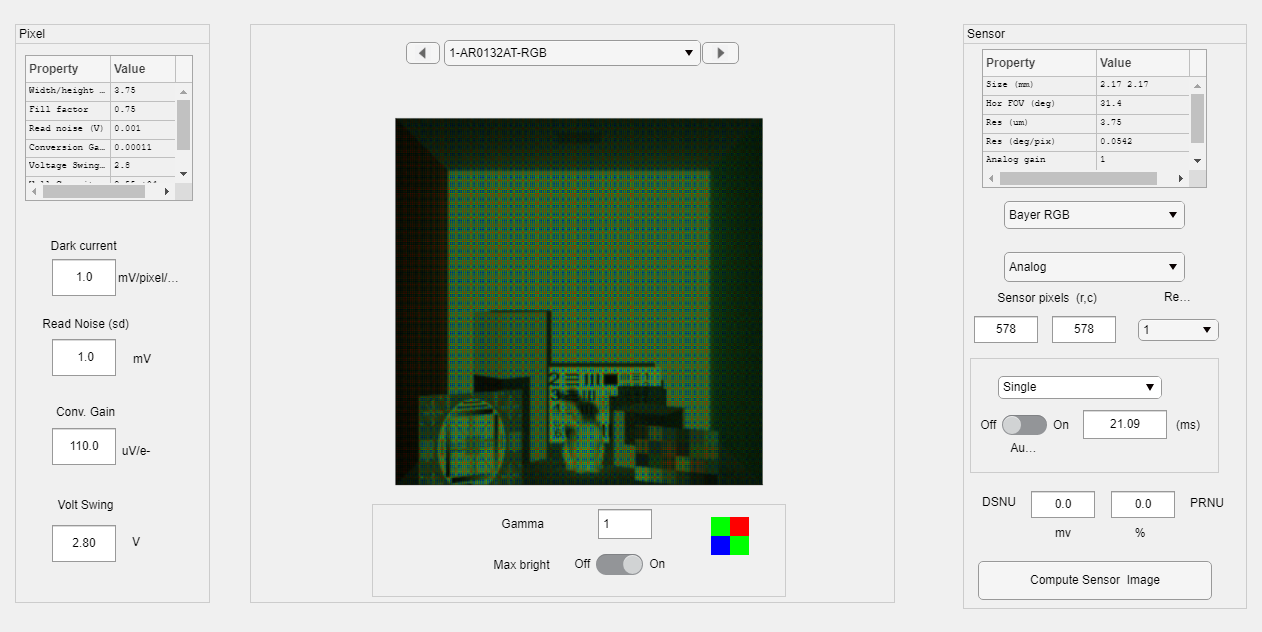

autoImage = ourCamera.TakePicture(pbrtCIScene, 'Auto',...
    'imageName','Auto Mode');

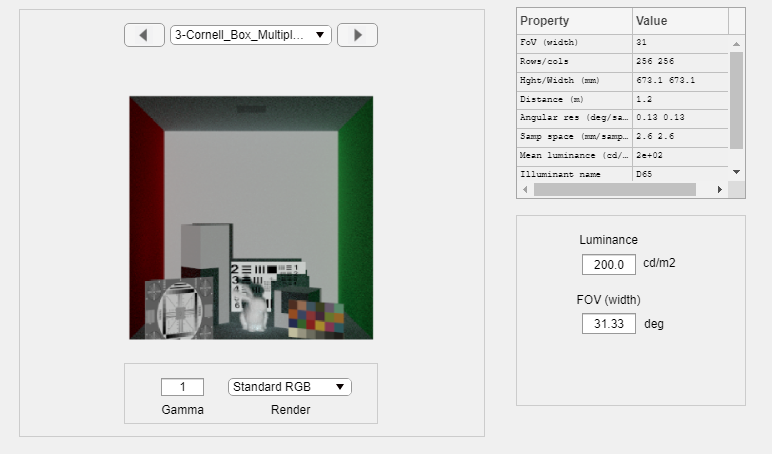

New light added.
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_depth.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cam

ans = "Scene luminance is: 200.000000"

New light added.
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_depth.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cam

ans = "Scene luminance is: 200.000000"

Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_depth.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts

ans = "Scene luminance is: 200.000000"

Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_depth.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts

ans = "Scene luminance is: 200.000000"

ieAddObject(autoImage); 

hdrImage = ourCamera.TakePicture(pbrtCIScene, 'HDR',...
    'numHDRFrames', 3,'imageName','HDR Example');

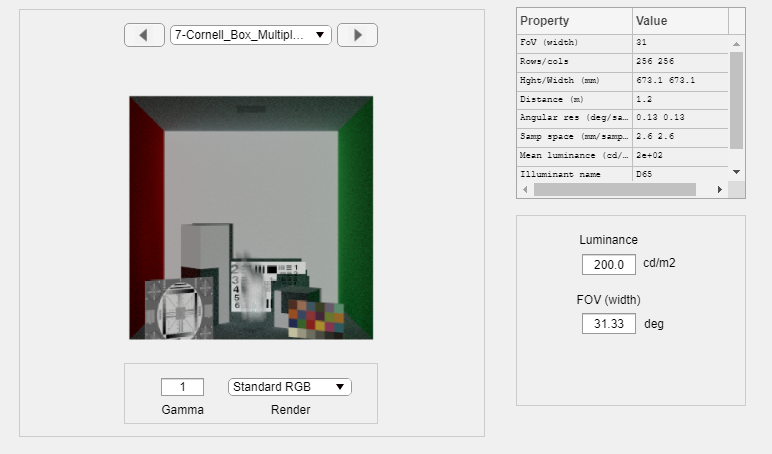

New light added.
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_depth.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cam

ans = "Scene luminance is: 200.000000"

New light added.
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_depth.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cam

ans = "Scene luminance is: 200.000000"

Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_depth.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts

ans = "Scene luminance is: 200.000000"

Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_depth.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts

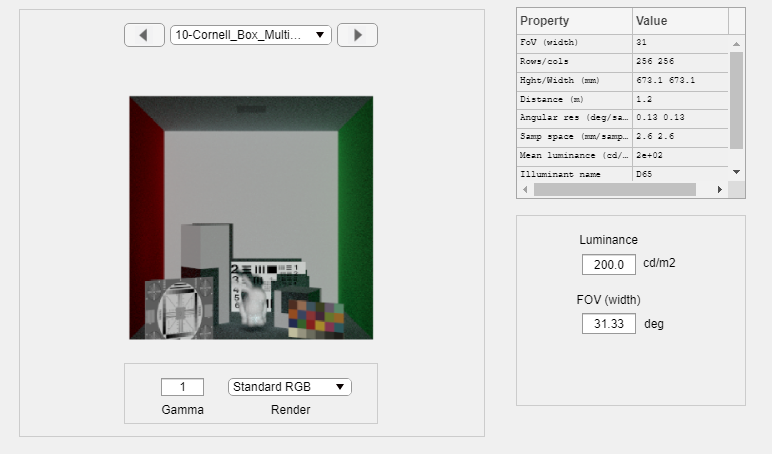

ans = "Scene luminance is: 200.000000"

ieAddObject(hdrImage); 

burstImage = ourCamera.TakePicture(pbrtCIScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst Example');

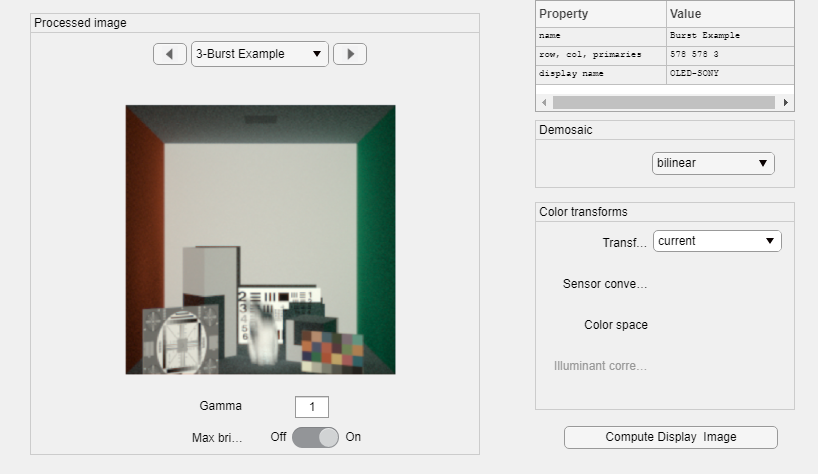

ieAddObject(burstImage); 

ipWindow(); % show the results

## Add Some Camera Motion

Note that we don't have a way to move the camera during frames (yet), so it only moves between frames. We also don't have a way to specify multiple cameras yet, so the first parameter is unused:

New light added.
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_depth.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cam

ans = "Scene luminance is: 200.000000"

New light added.
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_depth.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cam

ans = "Scene luminance is: 200.000000"

Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_depth.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts

ans = "Scene luminance is: 200.000000"

Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_depth.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts

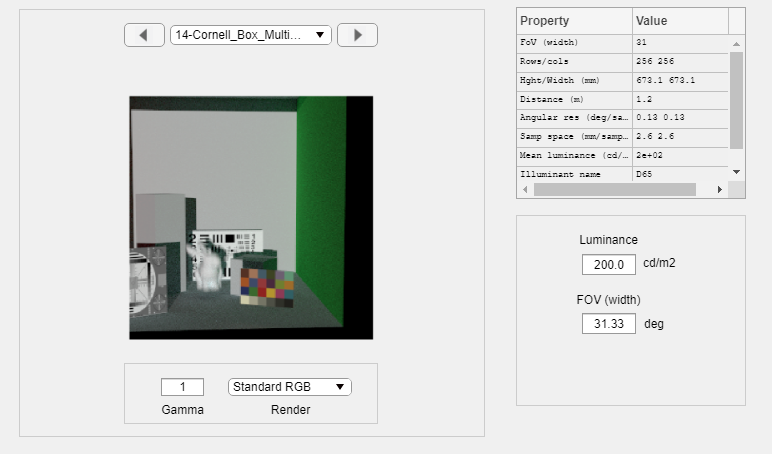

ans = "Scene luminance is: 200.000000"

pbrtCIScene.cameraMotion = {{'unused', [1, 0, 0], [2, 2, 2]}};

% now see what the burst looks like with the camera rotating and
% translating slightly, perhaps mimicing a user's hand motion
finalImage = ourCamera.TakePicture(pbrtCIScene, 'Burst', 'numBurstFrames', 3, 'imageName','Burst with Camera Motion');

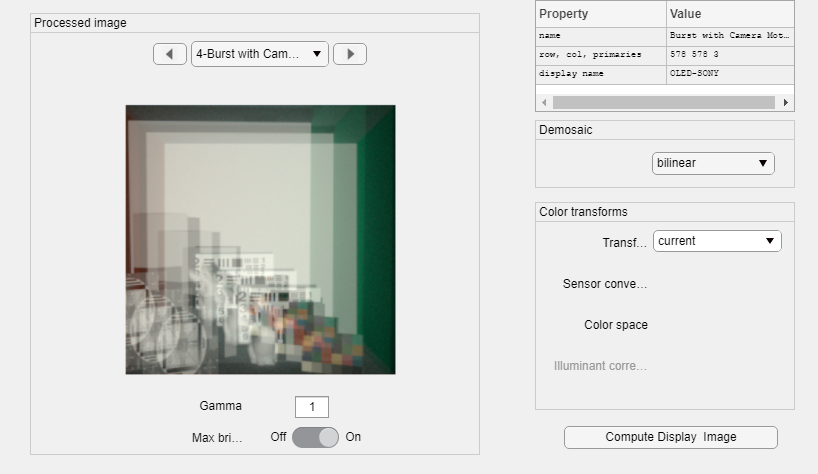

ieAddObject(finalImage);
ipWindow(); % show the result of a burst of images

## Look at the changes we've made to our camera

ciCameraWindow(ourCamera, pbrtCIScene);

## Working With ISET Scenes

While to get a fully-simulated 3D scene we need to use PBRT to render a Recipe, we can also take advantage of the variety of ISET Scenes (saved in .MAT files, or already loaded into ISET). Using them we can still emulate camera motion by moving the scene. 

ourSceneFile = fullfile('Feng_Office-hdrs.mat');
isetCIScene = ciScene('iset scene files', 'isetSceneFileNames', ourSceneFile, ...
    'sceneLuminance', sceneLuminance);

Reading multispectral data with mcCOEF.
Saved using svd method


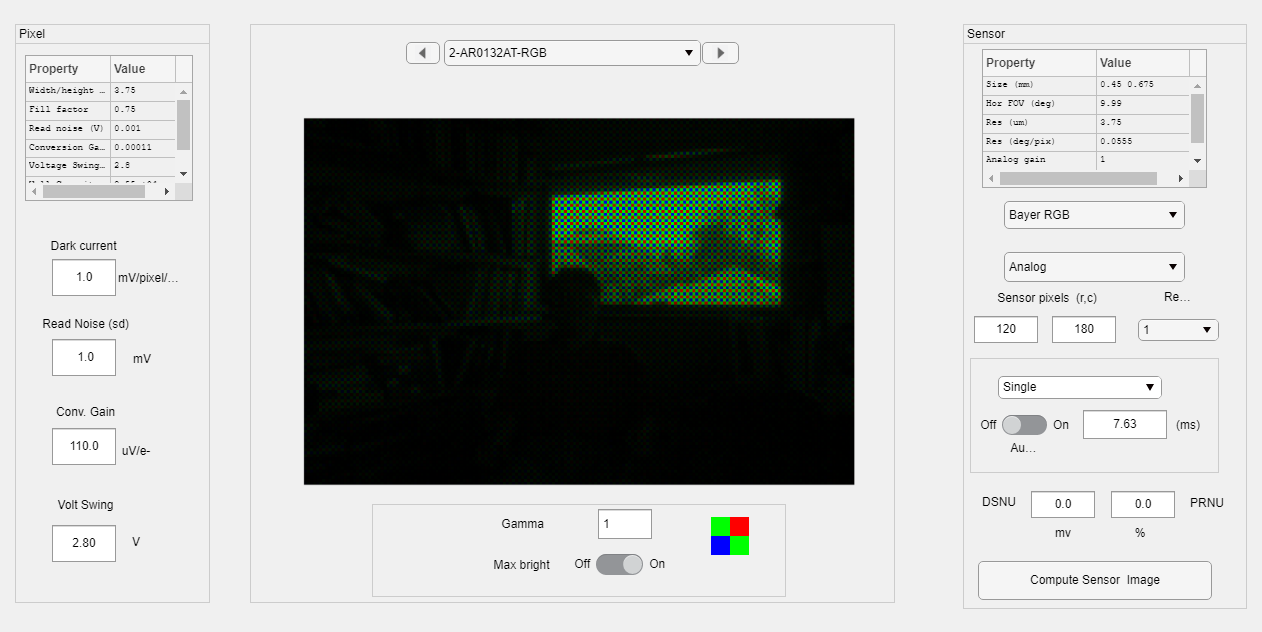


% We can use the same Camera object if we want, but with this new scene.
autoISETImage = ourCamera.TakePicture(isetCIScene, 'Auto',...
    'imageName','ISET Scene in Auto Mode');

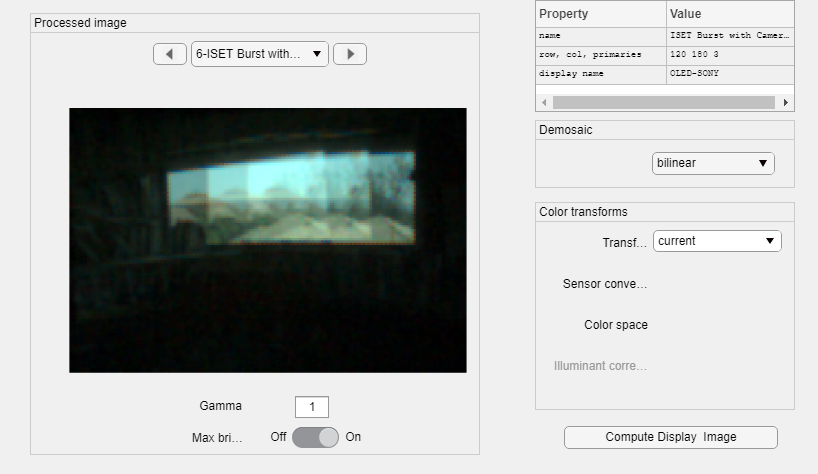

ieAddObject(autoISETImage); 

% Set camera motion, which is simulated for iset scenes 
% using scene motion
isetCIScene.cameraMotion = {{'unused', [1, 0, 0], [2, 2, 2]}};

% now see what the burst looks like with the the camera (scene) moving
finalImage = ourCamera.TakePicture(isetCIScene, 'Burst', 'numBurstFrames', 3, 'imageName','ISET Burst with Camera Motion');
ieAddObject(finalImage);
ipWindow(); % show the result of a burst of images

##  Working With Image Files

More sophisticated computational imaging algorithms typically rely on large data sets of training and test images. Neither of those exist in pbrt or iset format, so we also support standard RGB image files (.jpg, .png, etc.) We currently don't have a way to simulate object motion for these files, but we do support camera motion through simulating by moving the scene. Here we show an image using default rendering, and then with some camera motion and a burst of images. Note the color artifacts, since the default camera adds photosite values together in the raw sensor, but since the image has shifted, colors aren't correctly aligned:

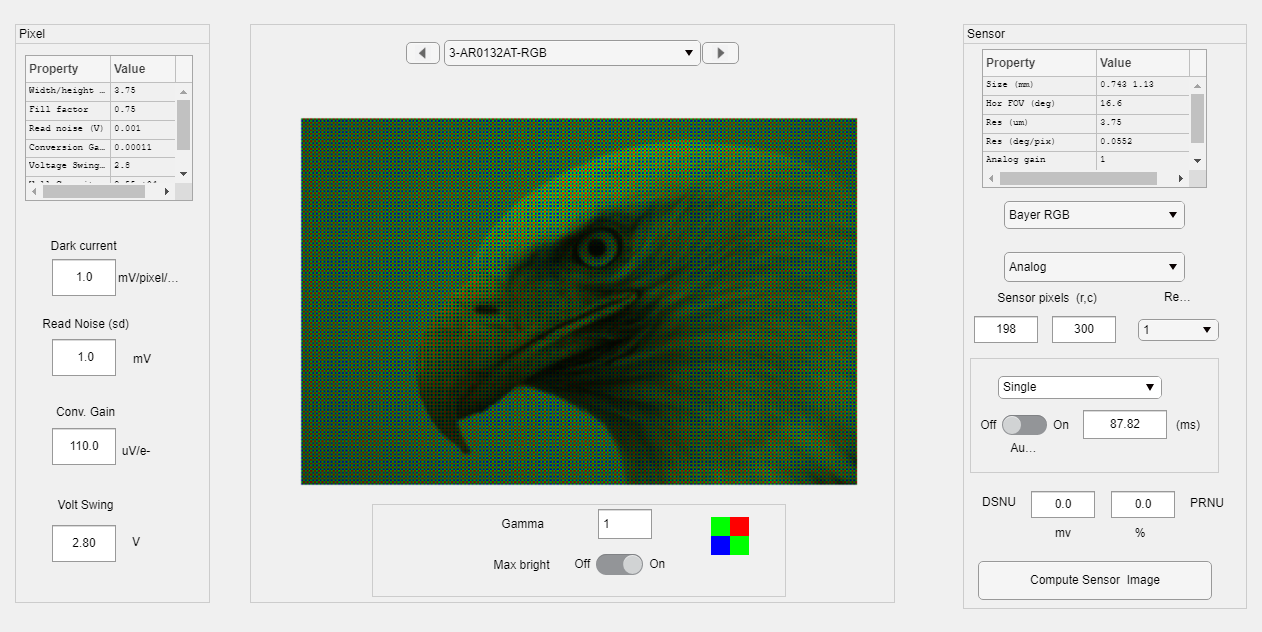

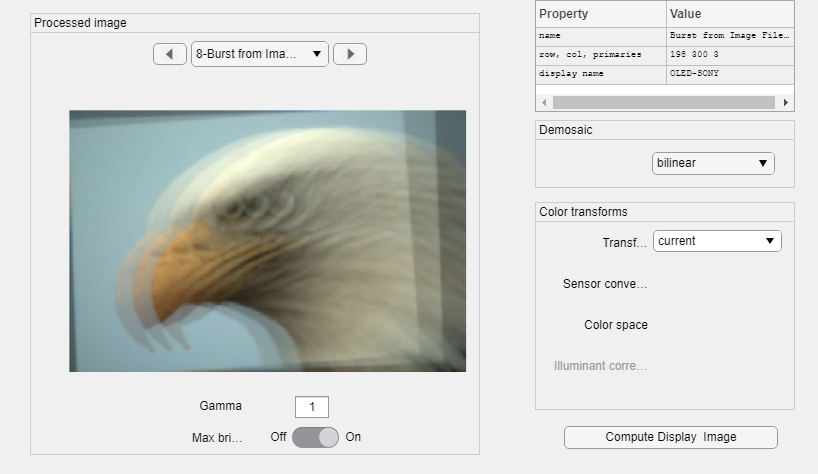

ourImageFile = 'eagle.jpg';
imageCIScene = ciScene('images', 'imageFileNames', ourImageFile);
% We can use the same ciCamera if we want
autoImageCapture = ourCamera.TakePicture(imageCIScene, 'Auto',...
    'imageName','Image File Captured in Auto Mode');
ieAddObject(autoImageCapture); 

% Set camera motion, which is simulated for iset scenes 
% using scene motion
imageCIScene.cameraMotion = {{'unused', [1, 0, 0], [2, 2, 2]}};

% now see what the burst looks like with the camera (scene) moving
finalImage = ourCamera.TakePicture(imageCIScene, 'Burst', 'numBurstFrames', 3, 'imageName','Burst from Image File with Camera Motion');
ieAddObject(finalImage);
ipWindow(); % show the result of a burst of images

## Using Pre-computed Scene and Object Motion

If we have access to a series of frames that illustrate either camera or object motion, we want to be able to use them directly. A simple example might be a series of frames from a video. To do that we can pass them as an array, either of ISET scenes or simply as image files

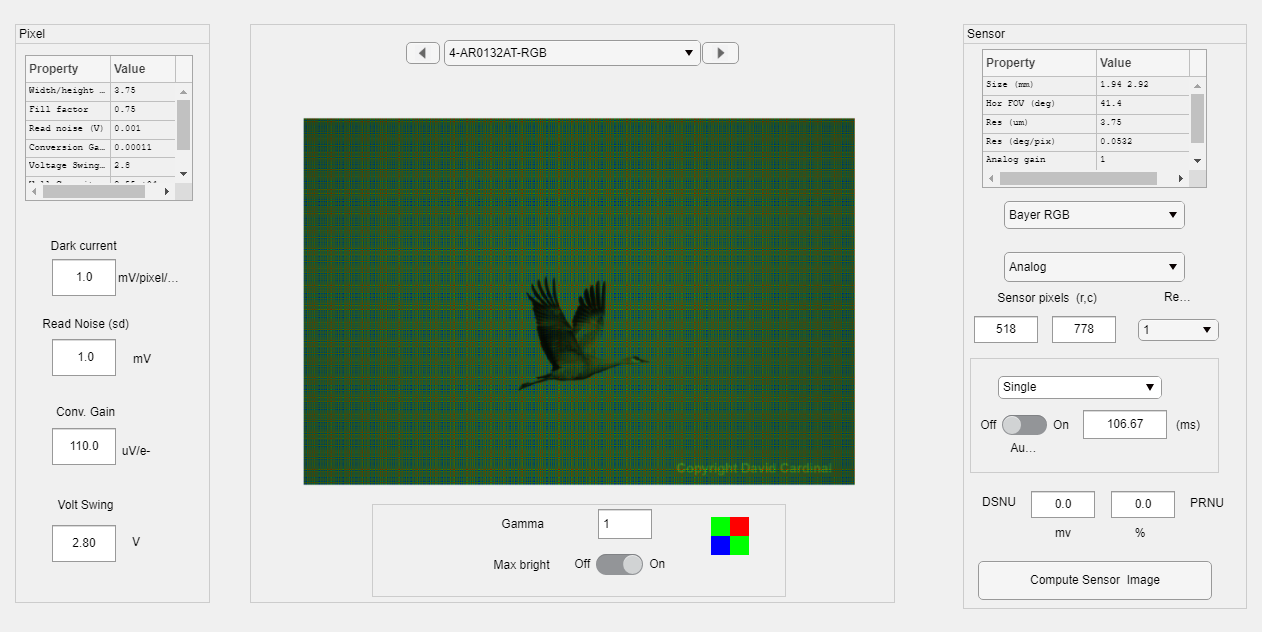

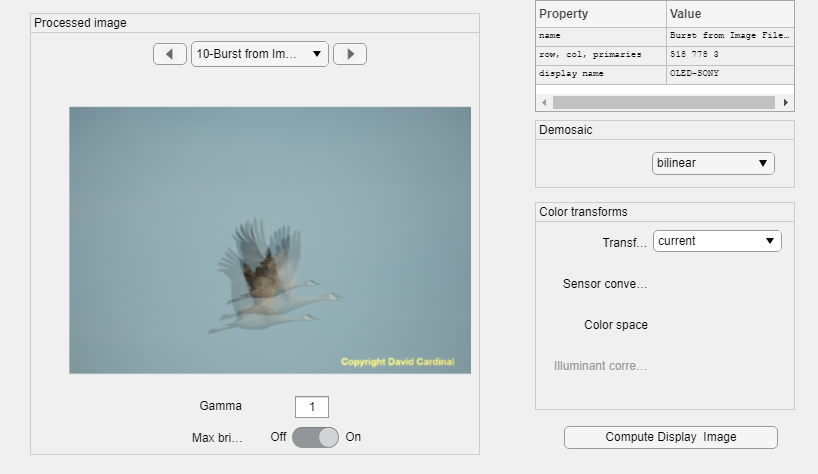

burstImageFiles = {'Crane_01.jpg', 'Crane_02.jpg', 'Crane_03.jpg'};
burstImagesCIScene = ciScene('images', 'imageFileNames', burstImageFiles, ...
   'resolution',[256, 256]);
% We can use the same ciCamera if we want
autoImagesCapture = ourCamera.TakePicture(burstImagesCIScene, 'Auto',...
    'imageName','Sequence of Image Files Captured in Auto Mode');
ieAddObject(autoImagesCapture); 

% Note that we can't add our own camera or object motion here, as we are
% simply using pre-computed scenes. Potentially we might want to support
% additional camera motion options, though?

% now see what the burst looks like with the camera (scene) moving
burstImage = ourCamera.TakePicture(burstImagesCIScene, 'Burst', 'numBurstFrames', 3, 'imageName','Burst from Image File with Camera Motion');
ieAddObject(burstImage);
ipWindow(); % show the result of a burst of images

## Using previously-captured Bracketed (HDR) Scenes

Here we'll render a set of bracketed images as scenes, and combine them using a simple HDR algorithm (largest non-saturated pixel at each location). In some areas, the result looks fairly good, while in other areas there is a dramatic color shift. In large part it is because we are combining the images in "sensor space" before de-mosaicing, and the initial images aren't aligned perfectly. 

As an exercise, consider either adding some alignment code or perhaps moving the HDR processing to after the de-mosaicing.

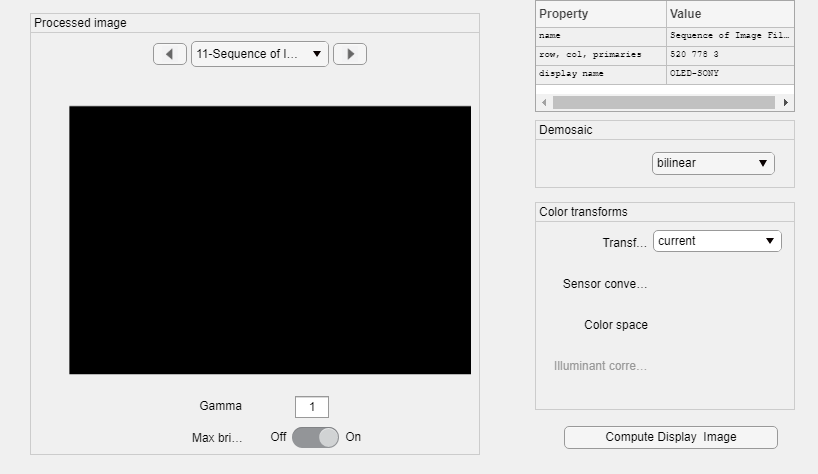


hdrImageFiles = {'BanteaySrei_01.jpg', 'BanteaySrei_02.jpg', 'BanteaySrei_03.jpg'};
hdrImagesCIScene = ciScene('images', 'imageFileNames', hdrImageFiles, ...
   'resolution',[256, 256]);
% We can use the same ciCamera if we want
hdrImagesCapture = ourCamera.TakePicture(hdrImagesCIScene, 'HDR',...
    'imageName','Sequence of Image Files Captured in HDR Mode');
ieAddObject(hdrImagesCapture); 
ipWindow();

## Test Focus Stacking code path

%stackedImage = ourCamera.TakePicture(pbrtCIScene, 'FocusStack',...
%    'imageName','Pretend Stack');
%ieAddObject(stackedImage); ipWindow();

## Print out some timing stats

Just for human consumption

tTotal = toc(getpref('ISET','tStart'));
afterTime = cputime;
beforeTime = getpref('ISET', 'benchmarkstart', 0);
glData = opengl('data');
disp(strcat("ciCam ran  on: ", glData.Vendor, " ", glData.Renderer, "with driver version: ", glData.Version)); 

ciCam ran  on: NVIDIA Corporation Quadro T2000/PCIe/SSE2with driver version: 4.6.0 NVIDIA 452.41


disp(strcat("ciCam ran  in: ", string(afterTime - beforeTime), " seconds of CPU time."));

ciCam ran  in: 688.9063 seconds of CPU time.


disp(strcat("ciCam ran  in: ", string(tTotal), " total seconds."));

ciCam ran  in: 572.1928 total seconds.
